format long
syms t
N=7;
N1=3;
x=[47; 49; 52; 53; 68; 70; 77];%создаю массив узлов для последующей выборки
y=[24; 24; 21; 43; 0.083; 45; 72];
'Метод наименьших квадратов'

ans = 'Метод наименьших квадратов'

A=[0 0; 0 0];
b=[0; 0];
for i=0:N1-2
    for k=0:N1-2
        for j=0:length(x)-1
            A(i+1,k+1)=A(i+1,k+1)+(x(j+1))^(k+i);
        end
    end
end
for i=0:N1-2
    for j=0:length(x)-1
        b(i+1,1)=b(i+1,1)+y(j+1)*(x(j+1))^i;
    end
end
a=inv(A)*b;%нахожу коэффициенты многочлена
a

a =  -20.218389558232996
   0.890893574297192


PNM1=@(t)a(2,1)*t+a(1,1);
PNM1(t)

$$ans = \frac{88733\,t}{99600}-\frac{5690970730030603}{281474976710656}$$

'Присвоение весов';
y_weight=[0;0;0;0;0;0;0];
for i=1:N
    y_weight(i)=y(i)/x(i);
end
y_weight;
y_weight_med=sort(y_weight);
med_y_weight=y_weight_med(4);
y_temp=[0;0;0;0;0;0;0];
for i=1:N
    y_temp(i)=y_weight(i)/med_y_weight;
end
y_temp

y_temp =    1.000000000000000
   0.959183673469388
   0.790865384615385
   1.588836477987422
   0.002390318627451
   1.258928571428572
   1.831168831168831


y_with_weight=[0;0;0;0;0;0;0];
for i=1:N
    y_with_weight(i)=y(i)*(y_weight(i)/med_y_weight);
end
y_with_weight;
'Взвешенный МНК'

ans = 'Взвешенный МНК'

A1=[0 0; 0 0];
b1=[0; 0];
for i=0:N1-2
    for k=0:N1-2
        for j=0:length(x)-1
            A1(i+1,k+1)=A1(i+1,k+1)+(x(j+1))^(k+i);
        end
    end
end
for i=0:N1-2
    for j=0:length(x)-1
        b1(i+1,1)=b1(i+1,1)+y_with_weight(j+1)*(x(j+1))^i;
    end
end
a1=inv(A1)*b1;%нахожу коэффициенты многочлена
a1

a1 =  -80.543322271887618
   2.125596023201317


PNM2=@(t)a1(2,1)*t+a1(1,1);
PNM2(t)

$$ans = \frac{2393208364507415\,t}{1125899906842624}-\frac{5667732440169607}{70368744177664}$$

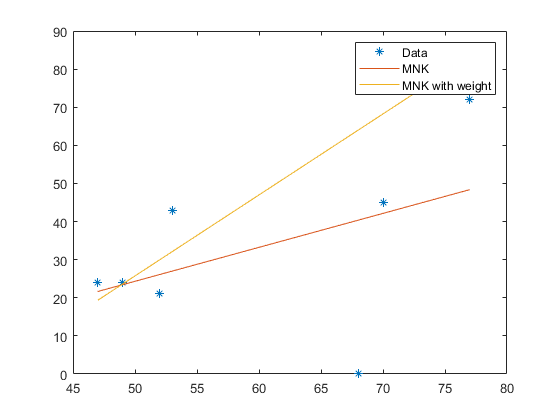

'Построение';
t=47:0.5:77;
plot(x,y,'*');
hold on
plot(t,PNM1(t));
plot(t,PNM2(t));
hold off
legend("Data","MNK","MNK with weight");